# Exam 1

Summer 2024

Math 3607

**Instruction.** Once complete, export this live script to pdf and upload the pdf file to Gradescope. Gradescope will be open until 10 minutes after the official end time of the exam. 

At the time of upload, Gradescope shows a list of problems and pages of your pdf file. Click each problem and select pages containing your solution for the problem. Failure to do so will incur point deduction.

**---------- BEGIN BY RUNNING THIS SECTION FIRST ----------**

clear, format compact, format long g

## Problem 1. (Fair dice rolls)

Simulate rolling 3 fair dice one million times to approximate the probability that three numbers rolled are all equal, e.g., rolling [1, 1, 1] or [2, 2, 2], etc. 

**Considerations.**

- To obtain maximum possible points, do this without using an if-statement or a loop.

- The only output I want to see is a single number, the approximate probability. Do not print out any intermediate results.

**Hint.**

- To write your code without a loop or a conditional statement, consider using `diff` function. For example, if your three rolls are [1, 3, 6] after you sort the numbers, applying `diff` on this will result in a vector [2, 3]. But if all three rolls are the same, e.g., [2, 2, 2], `diff` on this yields the zero vector [0, 0], which is relatively convenient to detect.

rng(2307)               % DO NOT REMOVE THIS.
% Your code begins below --------------------
rolls = randi(6, 1000000, 3); 
sorted_rolls = sort(rolls, 2); 
differences = diff(sorted_rolls, 1, 2); 
equal_rolls = sum(differences, 2) == 0; 
probability = mean(equal_rolls);

disp(probability);

                  0.027724



% The end of your code ----------------------

## Problem 2. (Closed surface)

Plot the surface represented (parametrically) by

$$\left\{ \; \begin{array}{rcl} x(\theta, \varphi) & = & (R + r \cos \theta) \cos \varphi \\ y(\theta, \varphi) & = & (R + r \cos \theta) \sin \varphi \\ z(\theta, \varphi) & = & r \sin \theta \end{array} \right.$$       for $\theta, \varphi \in [0, 2\pi]$.

You may use any values for $r$ and $R$ as long as $0 < r < R$. 

**Suggestions.**

- Use sufficiently many points so that the generated figure looks reasonably smooth.

- For visually pleasing results, it is recommended that you pick $R$ to be about 1.5 times larger than $r$.

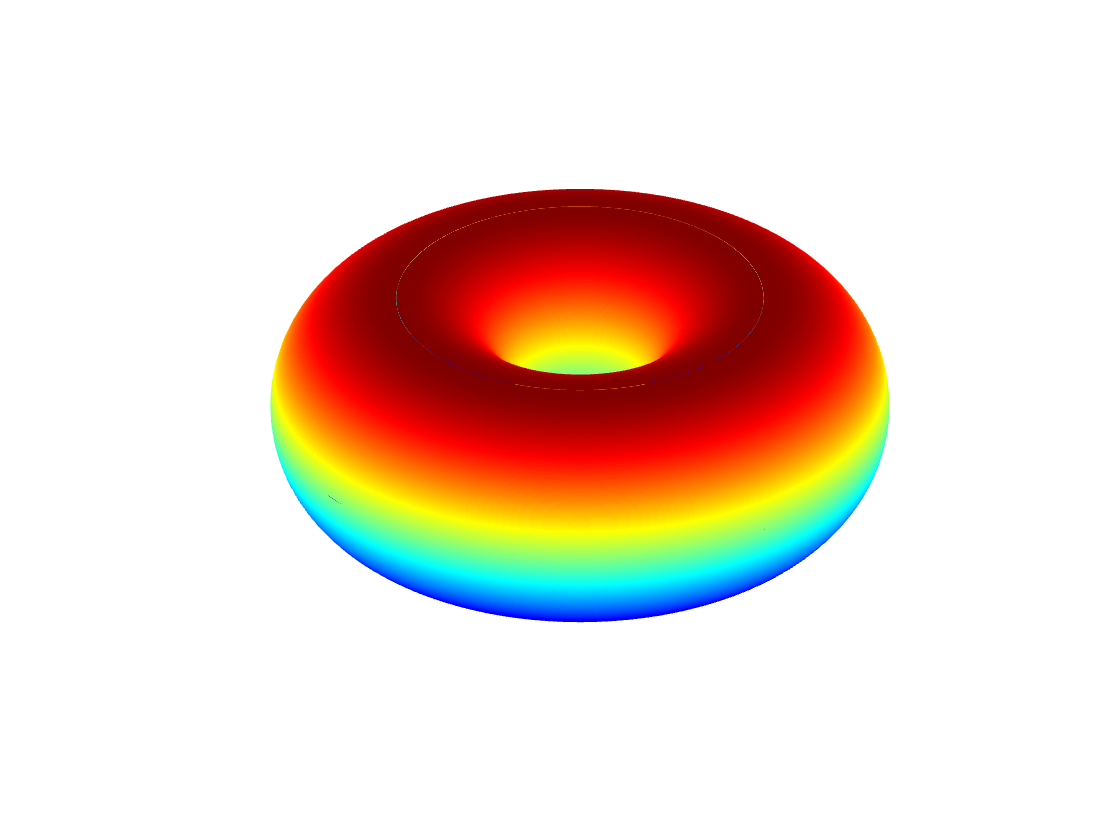

clf                     % DO NOT REMOVE THIS.
% Your code begins below --------------------
r = 1;
R = 1.5 * r; 
theta = linspace(0, 2*pi, 100);
phi = linspace(0, 2*pi, 100);

[Theta, Phi] = meshgrid(theta, phi);

X = (R + r * cos(Theta)) .* cos(Phi);
Y = (R + r * cos(Theta)) .* sin(Phi);
Z = r * sin(Theta);

surf(X, Y, Z);
shading interp;
colormap(jet);

% End of your code --------------------------
axis equal              % DO NOT REMOVE THIS.
axis off                % DO NOT REMOVE THIS.